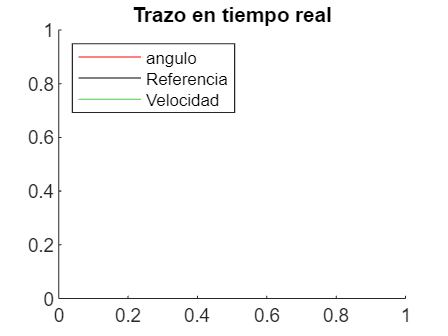

clear
clear device
clearvars
clearAllMemoizedCaches
clear ;clc;close all;
% load("TF.mat")
figure; 
hAxes(1) = gca; fig(1) = gcf;title("Trazo en tiempo real");legend("Location","northwest");%ylim([0 180]);
an(1)=animatedline(hAxes(1),'Color','r',"DisplayName","angulo");
an(2)=animatedline(hAxes(1),'Color','k',"DisplayName","Referencia");
an(3)=animatedline(hAxes(1),'Color','g',"DisplayName","Velocidad");



Gss2 = ss(G);
Gss2.StateName= {'Velocity','Position'};
Gss2.OutputName= {'Position'};

%Gss
Gss2

%polosO = [-2 -2.8]
%l = (acker(Gss.A',Gss.C',polosO))'

Q = 5*[1 0; 0 1]; %Función de peso para hacer veloz los estados y su convergencia a 0
R = 1; %Siempre positivo
L = -(lqr(Gss2.A',Gss2.C',Q,R))'

Agorro = Gss2.A+L*Gss2.C
Bgorro = [L Gss2.B]
Cgorro = Gss2.C

Obs = ss(Agorro,Bgorro,Cgorro,0)
Obs.InputName={'theta','V'}




prompt = {'Referencia:','Tiempo hasta siguiente prueba:'};
dlgtitle = 'Input';
dims = [1 35];
definput = {'40','20'};



device = serialport("COM9",115200);

Error using serialport
Unable to connect to the serialport device at port 'COM9'. Verify that a device is connected to the port, the port is not in
use, and all serialport input arguments and parameter values are supported by the device.
See related documentation for troubleshooting steps.

configureTerminator(device,"CR");



Ref=40;
writeline(device,"<"+string(Ref)+">")
readline(device);

i=1;
figure()
tPregunta=10;
while true
    
    
    Linea=readline(device);
    vals(i,:)=str2double(split(Linea)');
    addpoints(an(1),vals(i,2),vals(i,4)); %angulo sensor
    addpoints(an(2),vals(i,2),vals(i,5)); %referencia
    
    %addpoints(an(1),vals(i,2),vals(i,3)); %angulo sensor
    %addpoints(an(2),vals(i,2),vals(i,4)); %referencia

    if (vals(i,2)>tPregunta)
        try
            resInp = (inputdlg(prompt,dlgtitle,dims,definput));
            definput=resInp;
            RefN=str2num(resInp{1});
            tPregunta=vals(i,2)+str2num(resInp{2});
            if(~isnan(RefN)&&RefN~=Ref)
                Ref=RefN;
                writeline(device,"<"+string(Ref)+">");
            end
        catch ME
            tPregunta=vals(i,2)+10;
            %definput = {'90','10'};
            %definput = {'0','10'};
        end
    end
    i=i+1;
    
end

Error using split
First argument must be text.


DatosPID=vals(:,[2:5])


save("DatosPID.mat","DatosPID")